Load the dataset 

load fisheriris
X = meas(:,3:4);
Y = categorical(species);
labels = categories(Y);
tabulate(Y)

       Value    Count   Percent
      setosa       50     33.33%
  versicolor       50     33.33%
   virginica       50     33.33%


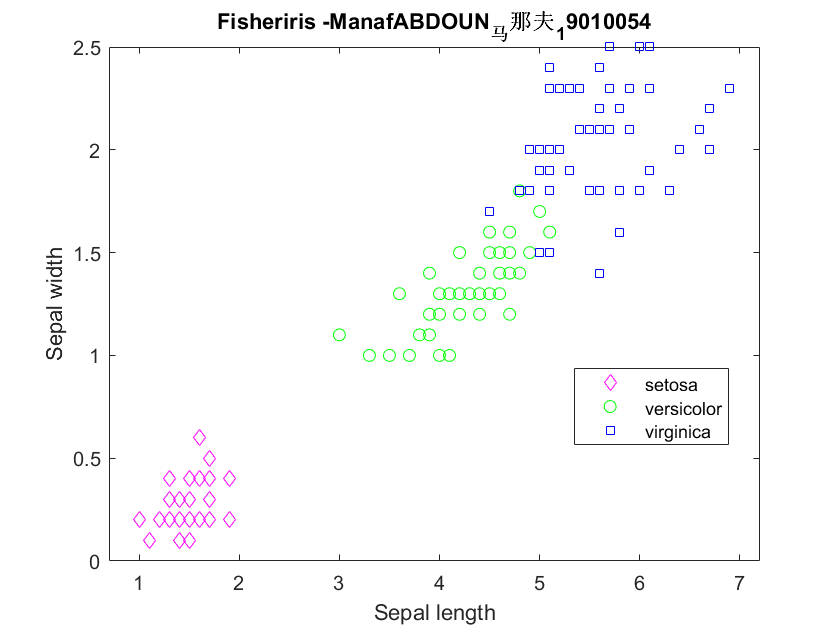

gscatter(X(:,1), X(:,2), species,'mgb','dos');
title('Fisheriris -ManafABDOUN_马那夫_19010054')
xlabel('Sepal length');
ylabel('Sepal width'); 

mdl = fitcnb(X,Y,'ClassNames',{'setosa','versicolor','virginica'});
setosaIndex = strcmp(mdl.ClassNames,'setosa');
estimates = mdl.DistributionParameters{setosaIndex,1}

estimates =     1.4620
    0.1737


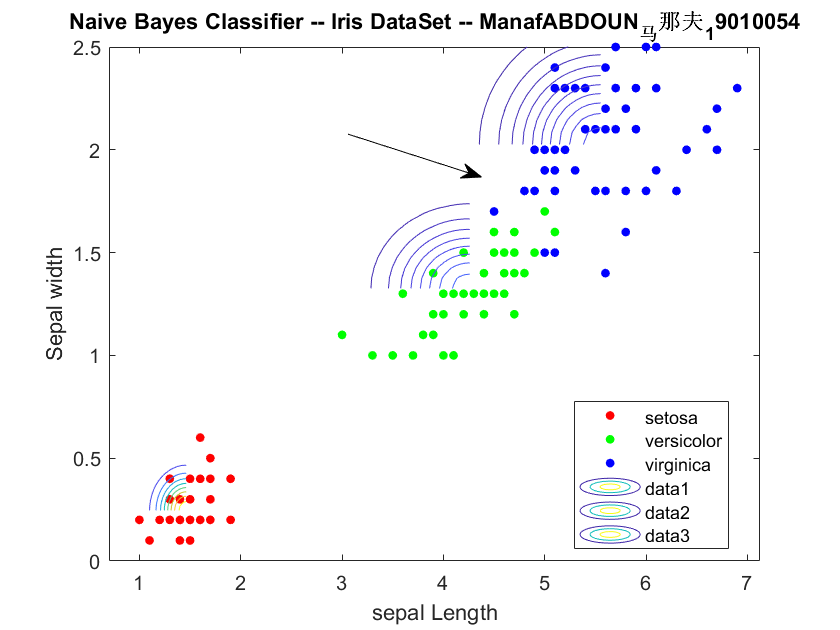

figure
gscatter(X(:,1), X(:,2), Y);
h = gca;
cxlim = h.XLim;
cylim = h.YLim;
hold on
Params = cell2mat (mdl.DistributionParameters);
Mu = Params(2*(1:3)-1,1:2);
Sigma = zeros(2,2,3);
for j = 1:3
    Sigma(:,:,j) = diag(Params(2*j,:)).^2;
    xlim = Mu(j,1) + 4*[1-1]*sqrt(Sigma(1,1,j));
    ylim = Mu(j,2) + 4*[1-1]*sqrt(Sigma(2,2,j));
    ezcontour(@(x1,x2)mvnpdf([x1,x2],Mu(j,:),Sigma(:,:,j)),[xlim ylim])
end
h.XLim = cxlim;
h.YLim = cylim;
title('Naive Bayes Classifier -- Iris DataSet -- ManafABDOUN_马那夫_19010054')
xlabel('sepal Length')
ylabel('Sepal width')
hold off

%Arrow Conflict zone
xlim([0.70 7.12])
ylim([0.00 2.50])
annotation('arrow',[0.4143 0.5732],[0.7871 0.719])